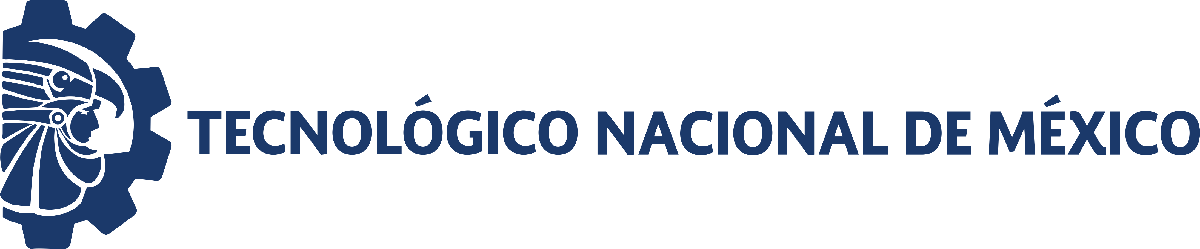                                 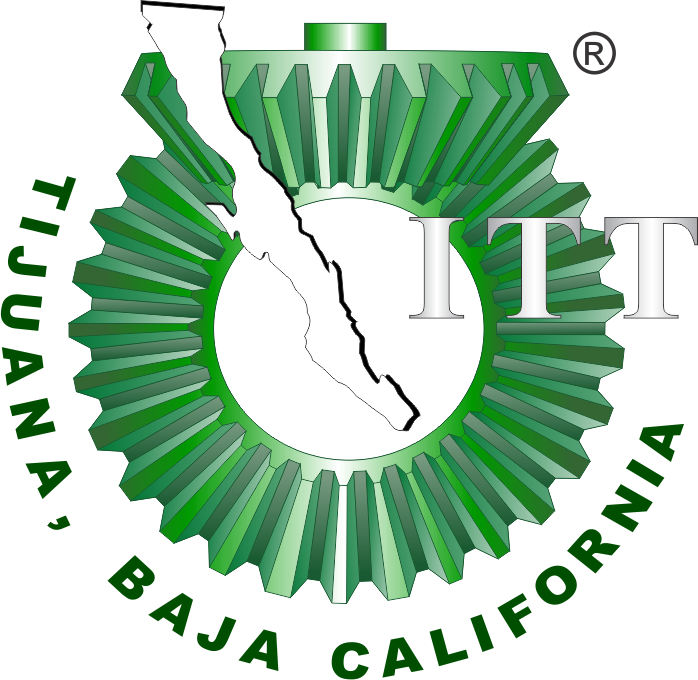

# Práctica 4: Modelizado matemático

**Departamento de Ingeniería Eléctrica y Electrónica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

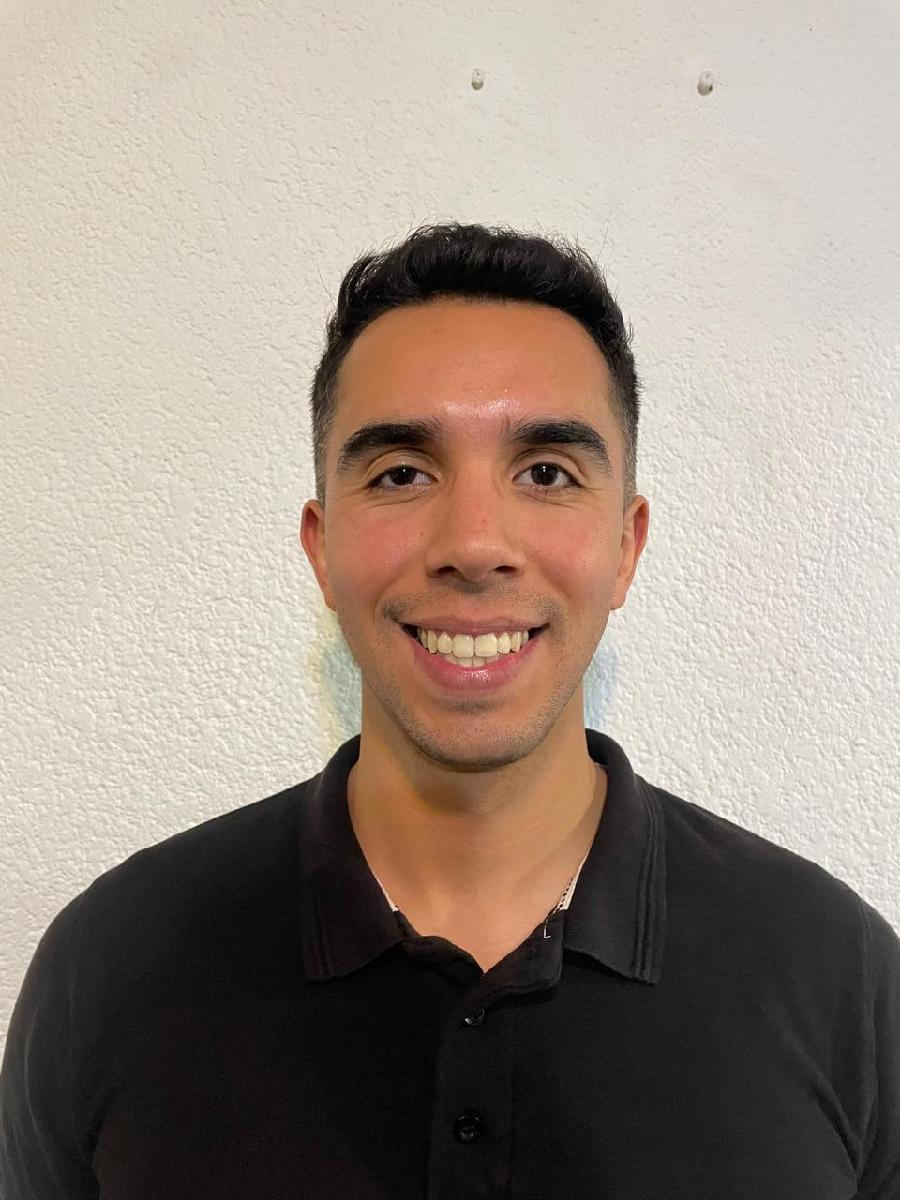

Nombre del alumno: **Carlos Andrés Gil Gárate**

Número de control: **21212743**

Correo institucional: **21212743@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Objetivo 

Construir y analizar un modelo mecanicista sobre de la dinámica entre dos variables biológicas.

## Modelo Matemático 

El modelo más simple y ampliamente utilizado para describir la interacción entre múltiples poblaciones es el tipo Lotka-Volterra. Existen otros modelos matemáticos sobre la cinética del crecimiento tumoral. Sin embargo, dado que todos estos modelos, incluido el de Lotka-Volterra, predicen el mismo comportamiento cualitativo, se optó por emplear el más sencillo de presentar y analizar matemáticamente.

### Algoritmo de Regresión No Lineal

De este modo, se formulan las ecuaciones de Lotka-Volterra considerando una población tumoral dominante y fenotípicamente estable (NT) que interactúa con células normales (NN).


$$\overset{\ldotp }{x} =p_{1x} \left(1-\frac{x+\gamma_1 y}{\beta }\right)$$



$$\overset{\ldotp }{x} =p_{2y} \left(1-\frac{y+\gamma_2 x}{\beta }\right)$$



$$\beta =10$$


## Simulation data

    Time     x(t)       y(t)  
    ____    _______    _______

      0     0.83086    0.99501
      5       1.662     2.5145
     10      2.2956     4.8358
     15       2.837     6.9758
     20      3.9255     6.9853
     25      3.9262     7.2348
     30      4.7409     6.7614
     35      4.5751     6.3823
     40      5.2588     6.3545
     45      5.1664     6.1724
     50      5.8318     6.0549
     55       6.006     4.8586
     60      5.8311     5.5353
     65      5.8493      5.113
     70      6.5819     5.3388
     75      6.8798     4.7416
     80      6.3799     4.5736
     85      6.8302     4.7893
     90      6.6908     4.1221
     95      7.1671     4.3096
    100      7.1736     4.6394
    105      6.6341      4.249
    110      7.3832      4.463
    115      7.5585     4.3067
    120      7.1246     4.1103
    125      7.5308     3.7325
    130      7.2664     4.118

clc; clear; close all; warning('off','all')
filename = 'data.csv';
sys = readmatrix(filename);
to= sys(:,1);
xo= sys(:,2);
yo= sys(:,3);
T = array2table([to,xo, yo], 'VariableNames', {'Time', 'x(t)', 'y(t)'});
disp(T); plotdata(to, xo, yo);

% Graficar datos experimentales
figure;
subplot(2,1,1); 
plot(to, xo, 'x', 'LineWidth', 1, 'MarkerSize', 4, 'Color','k');
xlabel('$Time [Days]$', 'Interpreter', 'latex');
ylabel('$x_i(t) [Cells]$', 'Interpreter', 'latex');
grid on;

subplot(2,1,2);
plot(to, yo, 'x', 'LineWidth', 1, 'MarkerSize', 4, 'Color', 'k');
xlabel('$Time [Days]$', 'Interpreter', 'latex');
ylabel('$y_i(t) [Cells]$', 'Interpreter', 'latex');
grid on;

### Algoritmo de regresión no lineal

P0 = [0.1; 0.1; 0.1; 0.1];
[mdl, xa, ya] = fitting_model(to, xo, yo, P0); 
plotresults(to, xo, yo, xa, ya);

## Equilibrium points and Jacobian matrix

clc; clear; close all; warning('off','all')
syms x y rho1 rho2 gamma1 gamma2 beta
dx = rho1*x*(1 - (x + gamma1*y)/beta);
dy = rho2*y*(1 - (y + gamma2*x)/beta);
J = jacobian([dx,dy],[x,y]);
fprintf('Jacobian matrix of the Lotka-Volterra system:'); disp(J)

Jacobian matrix of the Lotka-Volterra system:

$$\left(\begin{array}{cc} -\rho_{1}\,\left(\frac{x+\gamma_{1}\,y}{\beta }-1\right)-\frac{\rho_{1}\,x}{\beta } & -\frac{\gamma_{1}\,\rho_{1}\,x}{\beta }\\ -\frac{\gamma_{2}\,\rho_{2}\,y}{\beta } & -\rho_{2}\,\left(\frac{y+\gamma_{2}\,x}{\beta }-1\right)-\frac{\rho_{2}\,y}{\beta } \end{array}\right)$$

dx = rho1*x*(1 - (x + gamma1*y)/beta) == 0;
dy = rho2*y*(1 - (y + gamma2*x)/beta) == 0;
edos = solve([dx,dy],[x,y]);
fprintf(['The Lotka-Volterra system has ', num2str(length(edos.x)), ' equilibrium points.']);

The Lotka-Volterra system has 4 equilibrium points.

X0 = edos.x(1); Y0 = edos.y(1);
X1 = edos.x(2); Y1 = edos.y(2);
X2 = edos.x(3); Y2 = edos.y(3);
X3 = edos.x(4); Y3 = edos.y(4);
syms x0 y0 x1 y1 x2 y2 x3 y3
fprintf('Equilibrium points of the Lotka-Volterra system:'); disp([x0,y0,X0,Y0]); disp([x1,y1,X1,Y1]); disp([x2,y2,X2,Y2]); disp([x3,y3,X3,Y3]);

Equilibrium points of the Lotka-Volterra system:

$$\left(\begin{array}{cccc} x_{0} & y_{0} & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} x_{1} & y_{1} & \beta & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} x_{2} & y_{2} & 0 & \beta \end{array}\right)$$

$$\left(\begin{array}{cccc} x_{3} & y_{3} & \frac{\beta \,\left(\gamma_{1}-1\right)}{\gamma_{1}\,\gamma_{2}-1} & \frac{\beta \,\left(\gamma_{2}-1\right)}{\gamma_{1}\,\gamma_{2}-1} \end{array}\right)$$

clear gamma1 gamma2 beta
gamma1 = 0.67149;
gamma2 = 0.82706;
beta = 10;
disp('(x0,y0) = (0,0)'); disp(['(x1,y1) = (', num2str(beta),',',num2str(0),')']); disp(['(x2,y2) = (', num2str(0),',',num2str(beta),')']); disp(['(x3,y3) = (', num2str(beta * (gamma1 - 1) / (gamma1 * gamma2 - 1)),',',num2str(beta * (gamma2 - 1) / (gamma1 * gamma2 - 1)),')'])

(x0,y0) = (0,0)
(x1,y1) = (10,0)
(x2,y2) = (0,10)
(x3,y3) = (7.3883,3.8895)


### Local Stability

clc; clear; close all; warning('off','all')
gamma1 = 0.67149; gamma2 = 0.82706;
rho1 = 0.15265; rho2 = 0.27411;
beta = 10;
syms x y
dx = rho1*x*(1 - (x + gamma1*y)/beta) == 0;
dy = rho2*y*(1 - (y + gamma2*x)/beta) == 0;
edos = solve([dx,dy],[x,y]);
x0 = double(edos.x(1)); y0 = double(edos.y(1));
x1 = double(edos.x(2)); y1 = double(edos.y(2));
x2 = double(edos.x(3)); y2 = double(edos.y(3));
x3 = double(edos.x(4)); y3 = double(edos.y(4));
clear x y
x = [x0;x1;x2;x3]; y = [y0;y1;y2;y3];
var = {'(x0,y0)';'(x1,y1)';'(x2,y2)';'(x3,y3)'};
Equilibria = table(x,y,'RowNames',var);
Equilibria.Properties.VariableNames = {'xe','ye'};
fprintf('Equilibrium points of the Lotka-Volterra system:\n'); disp(Equilibria)

Equilibrium points of the Lotka-Volterra system:
                 xe        ye  
               ______    ______

    (x0,y0)         0         0
    (x1,y1)        10         0
    (x2,y2)         0        10
    (x3,y3)    7.3883    3.8895



L = zeros(length(x),2);
for i = 1:length(x)
     J = [-rho1 * ((x(i) + gamma1 * y(i)) / beta - 1) - rho1 * x(i) / beta, -rho1 * x(i) * gamma1 / beta;
         -rho2 * y(i) * gamma2 / beta, -rho2 * ((y(i) + gamma2 * x(i)) / beta - 1) - rho2 * y(i) / beta]
     L(i,:) = eig(J);
end

J =     0.1527         0
         0    0.2741


J =    -0.1527   -0.1025
         0    0.0474


J =     0.0501         0
   -0.2267   -0.2741


J =    -0.1128   -0.0757
   -0.0882   -0.1066


L1 = L(:,1); L2 = L(:,2);
Lambdas = table(L1,L2,'RowNames',var);
disp('Eigen values of the Jacobian matrix evaluated at each equilibrium point:'); disp(Lambdas)

Eigen values of the Jacobian matrix evaluated at each equilibrium point:
                  L1          L2    
               ________    _________

    (x0,y0)     0.15265      0.27411
    (x1,y1)    -0.15265     0.047405
    (x2,y2)    -0.27411     0.050147
    (x3,y3)    -0.19147    -0.027922



### Equilibrium Points Graphics 

clc; clear; close all;
sys = readmatrix('data.csv');
to = sys(:,1); 
xo = sys(:,2); 
yo = sys(:,3);
rho1 = 0.15265; gamma1 = 0.67149; 
rho2 = 0.27412; gamma2 = 0.82706;
P0 = [rho1,gamma1,rho2,gamma2];
[mdl, xa, ya] = Variant(to,xo,yo,P0); 


Sample size (n): 41
Parameters to be estimated (pars): 4
Degrees of freedom: 78
Significance level (alpha): 0.05
t-Student value: 1.9908
R-squared: 0.97421
Corrected AIC (n/pars < 40): 25.358

    Parameters    Estimate       SE          MoE              CI95             pvalue  
    __________    ________    _________    ________    __________________    __________

      rho1        0.15265     0.0053859    0.010722    0.14193    0.16337    8.0499e-43
      gamma1      0.67149      0.012893    0.025668    0.64582    0.69716    2.3483e-62
      rho2        0.27412      0.011137    0.022172    0.25195     0.2963    1.6168e-38
      gamma2      0.82706     0.0083655    0.016654    0.81041    0.84371    9.9957e-84



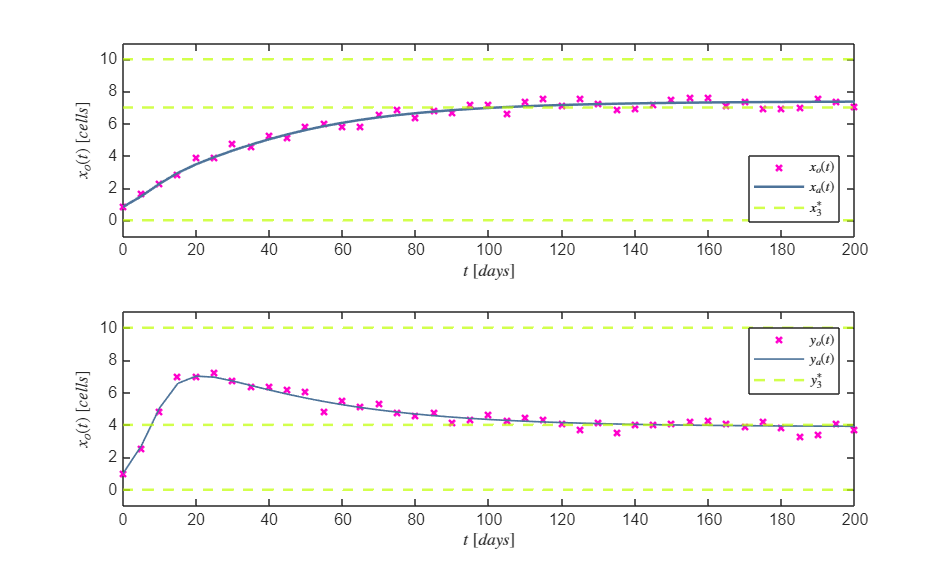

plotpoints(to,[xo,xa],[yo,ya])

## Conclusión

El sistema modelado muestra múltiples puntos de equilibrio, de los cuales uno presenta estabilidad local. Esta estabilidad se verifica mediante el análisis de los autovalores del Jacobiano, los cuales indican un comportamiento marginal en dicho punto, correspondiente a un centro. Los demás puntos de equilibrio muestran inestabilidad debido a la presencia de valores propios reales positivos, lo cual concuerda con el comportamiento cualitativo esperado en modelos de interacción competitiva entre poblaciones celulares.

## Functions 

### Plot Experimental Data

function plotdata(to, xo, yo)
    nrj = [0.8500 0.3250 0.0980];  % Naranja
    amr = [0.9290 0.6940 0.1250];  % Amarillo
    vrd = [0.4660 0.6740 0.1880];  % Verde
    mor = [0.4940 0.1840 0.5560];  % Morado

    blanco = [1 1 1];              % Fondo blanco
    gris_lineas = [0.7 0.7 0.7];   % Gris medio para cuadrícula

    fig = figure();
    set(fig, 'Color', blanco)
    FS = 11;
    set(gcf, 'Units', 'Centimeters', 'Position', [2,2,25,10])

    subplot(2,1,1)
    plot(to, xo, 'x', 'LineWidth', 1, 'MarkerSize', 5, 'Color', nrj)
    hold on
    xlabel('$t [days]$', 'Interpreter', 'Latex', 'FontSize', FS)
    ylabel('$x_o(t) [cells]$', 'Interpreter', 'Latex', 'FontSize', FS)
    xlim([0 200]); xticks(0:20:200)
    ylim([0 10]); yticks(0:2:10)
    grid on
    ax1 = gca;
    ax1.GridColor = gris_lineas;
    ax1.Color = blanco;

    subplot(2,1,2)
    plot(to, yo, 'x', 'LineWidth', 1, 'MarkerSize', 5, 'Color', mor)
    hold on
    xlabel('$t [days]$', 'Interpreter', 'Latex', 'FontSize', FS)
    ylabel('$y_o(t) [cells]$', 'Interpreter', 'Latex', 'FontSize', FS)
    xlim([0 200]); xticks(0:20:200)
    ylim([0 10]); yticks(0:2:10)
    grid on
    ax2 = gca;
    ax2.GridColor = gris_lineas;
    ax2.Color = blanco;

    sgtitle('Experimental data', 'FontSize', FS + 2, 'FontWeight', 'bold');

    saveas(gcf, 'Experimental Data.png')
end

### Plot Experimental Modelling

function plotresults(to, xo, yo, xa, ya)
    nrj = [0.8500 0.3250 0.0980];  % Naranja
    amr = [0.9290 0.6940 0.1250];  % Amarillo
    vrd = [0.4660 0.6740 0.1880];  % Verde
    mor = [0.4940 0.1840 0.5560];  % Morado
    naj = [0.8500 0.3250 0.0980];  % Naranja (repetido)
    ne = [0.00, 0.00, 0.00];       % Negro
    gris_lineas = [0.7 0.7 0.7];   % Gris claro para la cuadrícula

    set(figure(), 'Color', 'w')
    FS = 11;
    set(gcf, 'Units', 'Centimeters', 'Position', [2,2,25,10])

    subplot(2,1,1)
    plot(to, xo, 'x', 'LineWidth', 1, 'MarkerSize', 4, 'Color', ne)  % círculo negro
    hold on
    plot(to, xa, '-', 'LineWidth', 1, 'Color', vrd)
    xlabel('$t [days]$', 'Interpreter', 'Latex', 'fontsize', FS)
    ylabel('$x(t) [cells]$', 'Interpreter', 'Latex', 'fontsize', FS)
    xlim([0 200]); xticks(0:20:200)
    ylim([0 10]); yticks(0:2:10)
    grid on
    ax1 = gca;
    ax1.GridColor = gris_lineas;
    ax1.Color = 'w';
    set(ax1, 'FontName', 'Times New Roman', 'FontSize', FS)
    L = legend('$x_o(t)$', '$x_{fit}(t)$');
    set(L, 'Interpreter', 'Latex', 'fontsize', FS, 'Location', 'SouthEast')

    subplot(2,1,2)
    plot(to, yo, 'x', 'LineWidth', 1, 'MarkerSize', 4, 'Color', ne)  % círculo negro
    hold on
    plot(to, ya, '-', 'LineWidth', 1, 'Color', mor)
    xlabel('$t [days]$', 'Interpreter', 'Latex', 'fontsize', FS)
    ylabel('$y(t) [cells]$', 'Interpreter', 'Latex', 'fontsize', FS)
    xlim([0 200]); xticks(0:20:200)
    ylim([0 10]); yticks(0:2:10)
    grid on
    ax2 = gca;
    ax2.GridColor = gris_lineas;
    ax2.Color = 'w';
    set(ax2, 'FontName', 'Times New Roman', 'FontSize', FS)
    L = legend('$y_o(t)$', '$y_{fit}(t)$');
    set(L, 'Interpreter', 'Latex', 'fontsize', FS, 'Location', 'NorthEast')

    saveas(gcf, 'plotmodel.png')
end


function [mdl, xa, ya] = fitting_model(to, xo, yo, P0)
    fo = [xo; yo]; 
    to = [to; to]; 
    x0 = xo(1); 
    y0 = yo(1); 
    beta = 10;

    function fa = model(P, t)
        t = reshape(t, [], 2);
        t = t(:,1);
        rho1 = P(1); 
        gamma1 = P(2); 
        rho2 = P(3); 
        gamma2 = P(4);
        dt = 1E-2;
        time = (0:dt:max(t))';
        n = round(max(t) / dt);
        x = zeros(n+1, 1); 
        x(1) = x0;
        y = zeros(n+1, 1); 
        y(1) = y0;

        for i = 1:n
            [fx, fy] = f(x(i), y(i));
            xn = x(i) + fx * dt;
            yn = y(i) + fy * dt;
            [fxn, fyn] = f(xn, yn);
            x(i+1) = x(i) + (fx + fxn) * dt / 2;
            y(i+1) = y(i) + (fy + fyn) * dt / 2;
        end

        function [dx, dy] = f(x, y)
            dx = rho1 * x * (1 - (x + gamma1 * y) / beta);
            dy = rho2 * y * (1 - (y + gamma2 * x) / beta);
        end

        xi = zeros(length(t), 1);
        yi = zeros(length(t), 1);
        for i = 1:length(t)
            k = find(abs(time - t(i)) < 1E-9, 1);
            if ~isempty(k)
                xi(i) = x(k);
                yi(i) = y(k);
            end
        end

        fa = [xi; yi];
    end

    mdl = fitnlm(to, fo, @model, P0);
    
    % Obtener valores ajustados correctamente usando predict
    fitted_values = predict(mdl, to);
    xa = fitted_values(1:length(xo));
    ya = fitted_values(length(xo)+1:end);
    
    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    CI95 = coefCI(mdl, 0.05);
    Pvalue = table2array(mdl.Coefficients(:,4));
    dof = mdl.DFE;
    alpha = 0.05;
    tval = tinv(1 - alpha / 2, dof);
    MoE = SE * tval;
    Parameters = ['rho1  '; 'gamma1'; 'rho2  '; 'gamma2'];
    fit = table(Parameters, Estimate, SE, MoE, CI95, Pvalue);
    disp(fit);
end

### Plot Equilibrium Points

function plotpoints(to, xo, yo)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    set(gca,'FontName','Times New Roman')
    set(gca, 'FontSize', 12)  
    
    Mecambiareaindustrial = [
        0.60, 0.00, 0.00;  
        0.75, 1.00, 0.00;  
        0.00, 0.75, 1.00;  
        0.50, 0.00, 0.75;
        1.00, 0.50, 0.00;  
        0.40, 0.20, 0.10;  
        1.00, 0.00, 0.80;  
        1.00, 0.85, 0.00; 
        0.00, 0.85, 0.65;  
        0.30, 0.45, 0.60   
    ];    
    rng('shuffle'); 
    indices = randperm(size(Mecambiareaindustrial,1), 3); 
    c1 = Mecambiareaindustrial(indices(1), :);
    c2 = Mecambiareaindustrial(indices(2), :);
    c3 = Mecambiareaindustrial(indices(3), :);

    subplot(2,1,1)
    hold on; box on; grid off;
    plot(to, xo(:,1), 'x', 'MarkerSize', 5, 'LineWidth', 1.5, 'Color', c1)
    plot(to, xo(:,2), '-', 'LineWidth', 1.5, 'Color', c2)
    yline(10, '--', 'LineWidth', 1.5, 'Color', c3)
    yline(0, '--', 'LineWidth', 1.5, 'Color', c3)
    yline(7, '--', 'LineWidth', 1.5, 'Color', c3)
    xlabel('$t$ $[days]$', 'Interpreter', 'latex')
    ylabel('$x_o(t)$ $[cells]$', 'Interpreter', 'latex')
    L = legend('$x_o(t)$', '$x_a(t)$', '$x^*_3$');
    set(L, 'Interpreter', 'latex', 'Location', 'Best', 'Box', 'On')
    xlim([0 200]); xticks(0:20:200)
    ylim([-1 11]); yticks(0:2:10)

    subplot(2,1,2)
    hold on; box on; grid off;
    plot(to, yo(:,1), 'x', 'MarkerSize', 5, 'LineWidth', 1.5, 'Color', c1)
    plot(to, yo(:,2), '-', 'LineWidth', 1, 'Color', c2)
    yline(10, '--', 'LineWidth', 1.5, 'Color', c3)
    yline(0, '--', 'LineWidth', 1.5, 'Color', c3)
    yline(4, '--', 'LineWidth', 1.5, 'Color', c3)

    xlabel('$t$ $[days]$', 'Interpreter', 'latex')
    ylabel('$x_o(t)$ $[cells]$', 'Interpreter', 'latex')
    L = legend('$y_o(t)$', '$y_a(t)$', '$y^*_3$');
    set(L, 'Interpreter', 'latex', 'Location', 'Best', 'Box', 'On')
    xlim([0 200]); xticks(0:20:200)
    ylim([-1 11]); yticks(0:2:10)
end

### Plot Variant 

function [mdl,xa,ya] = Variant(to,xo,yo,P0)
    x0 = xo(1); y0 = yo(1);
    to = [to;to];
    fo = [xo;yo];

    function fi = model(p,t)
        rho1 = p(1); gamma1 = p(2); rho2 = p(3); gamma2 = p(4);
        dt = 1E-1;
        t = reshape (t,[],2); t = t(:,1);
        time = (0:dt:max(t))';
        n = round(max(t)/dt);
        x = zeros(n+1,1); x(1) = x0;
        y = zeros(n+1,1); y(1) = y0;

        for i = 1:n
            [fx,fy] = f(x(i),y(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            [fxn,fyn] = f(xn,yn);

            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
        end

        function [dx,dy] = f(x,y)
            dx = rho1*x*(1-((x+gamma1*y)/10));
            dy = rho2*y*(1-((y+gamma2*x)/10));
        end 
        xi = zeros(length(t),1);
        yi = zeros(length(t),1);
        for j = 1:length(t)
            k = abs(time-t(j)) < 1E-9;
            xi(j) = x(k);
            yi(j) = y(k);
        end
        fi = [xi;yi];
    end

    mdl = fitnlm(to,fo,@model,P0);

    fa = mdl.Fitted;
    fx = reshape(fa,[],2);
    xa = fx(:,1); ya = fx(:,2);

    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    CI95 = coefCI(mdl,alpha);
    dof = mdl.DFE;
    tval = tinv(1-alpha/2,dof);
    MoE = SE*tval;
    Parameters = ['rho1  ';'gamma1';'rho2  ';'gamma2';];
    Results = table(Parameters,Estimate,SE,MoE,CI95,pvalue);

    fprintf(['\nSample size (n): ', num2str(numel(xo))]) 
    fprintf(['\nParameters to be estimated (pars): ', num2str(numel(P0))])
    fprintf(['\nDegrees of freedom: ', num2str(dof)])
    fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
    fprintf(['\nt-Student value: ', num2str(tval)])
    fprintf(['\nR-squared: ', num2str(mdl.Rsquared.Ordinary)])
    fprintf(['\nCorrected AIC (n/pars < 40): ', num2str(mdl.ModelCriterion.AICc),'\n\n'])
    disp(Results)
end

## Referencias 

[1]  Paul. A. Valle, Syllabus de Biomatemáticas para la asignatura de Gemelos Digitales, Tecnológico Nacional de México/IT Tijuana, Tijuana, B.C., México, 2025. Permalink: https://www.dropbox.com/s/6yf9afxzih9y458/Biomatematicas.pdf

[2] Dominik Wordaz & Natalia L. Komarova, Dynamics of Cancer: Mathematical Foundations of Oncology, University of California, Irvine, USA, 2014.

[3] Robert A. Gatenby & Thomas L. Vincent, "Application of quantitative models from population biology and evolutionary game theory to tumor therapeutic strategies," Molecular Cancer Therapeutics, vol. 2, no. 9, pp. 919–927, Jun 2003.